# **Projeto ATD**

**Feito por:**

Diogo Henriques-2019222685

Diogo Alves-2020214197

## EX1&2- Construção de uma tabela com informações dos audios e os seus sinais e taxas de amostragem


clc; clear; close all;

% Diretório base onde os ficheiros estão armazenados
diretorio_base = fullfile(pwd, 'data');

% Obter a lista de pastas (participantes)
pastas = dir(diretorio_base);
pastas = pastas([pastas.isdir] & ~startsWith({pastas.name}, '.')); % Remover '.' e '..'

% Inicializar variáveis
diretorios = {};
nomes_ficheiros = {};
participantes = [];
digitos = [];
repeticoes = [];
taxas_de_amostragem = [];
sinais={};
% Percorrer cada pasta (participante)
for i = 1:length(pastas)
    pasta_participante = fullfile(diretorio_base, pastas(i).name);
    
    % Listar os ficheiros na pasta do participante
    ficheiros = dir(fullfile(pasta_participante, '*.wav'));
    
    for j = 1:length(ficheiros)
        nome_ficheiro = ficheiros(j).name;
        caminho_ficheiro = fullfile(pasta_participante,nome_ficheiro);

        % Separar o nome do ficheiro pelo caractere "_"
        partes = split(nome_ficheiro, '_');

        % Garantir que há pelo menos 3 elementos
        if length(partes) >= 3
            participante = str2double(partes{2}); % O segundo elemento é o participante
            digito = str2double(partes{1});       % O terceiro elemento é o dígito
            
            % Garantir que há um quarto elemento antes de acessá-lo

            repeticao = str2double(extractBefore(partes{3}, '.wav')); % Remover extensão
            
            [y,fs] = audioread(caminho_ficheiro);
            

            % Guardar os valores nas listas
            diretorios{end+1} = pasta_participante;
            nomes_ficheiros{end+1} = nome_ficheiro;
            participantes(end+1) = participante;
            digitos(end+1) = digito;
            repeticoes(end+1) = repeticao;
            taxas_de_amostragem (end+1) = fs;
            sinais{end+1} = y;  % Armazenar o sinal na célula
        else
            warning('Ficheiro com nome inesperado: %s', nome_ficheiro);
        end
    end
end

% Criar a tabela com os dados
dados_audio = table(diretorios', nomes_ficheiros', participantes', digitos', repeticoes', taxas_de_amostragem', sinais', ...
                    'VariableNames', {'Diretorio', 'NomeFicheiro', 'Participante', 'Digito', 'Repeticao', 'Taxa_de_amostragem', 'Sinal'});
% Salvar a tabela em um ficheiro .mat
save('dados_audio.mat', 'dados_audio');
% Exibir a tabela
disp(dados_audio);

                         Diretorio                          NomeFicheiro      Participante    Digito    Repeticao    Taxa_de_amostragem         Sinal      
    ___________________________________________________    _______________    ____________    ______    _________    __________________    ________________

    {'C:\Users\Legion\Desktop\ATD\Projeto\ATD\data\01'}    {'0_01_0.wav' }         1            0           0              48000           {35877×1 double}
    {'C:\Users\Legion\Desktop\ATD\Projeto\ATD\data\01'}    {'0_01_1.wav' }         1            0           1              48000           {31356×1 double}
    {'C:\Users\Legion\Desktop\ATD\Projeto\ATD\data\01'}    {'0_01_10.wav'}         1            0          10              48000         

Todos os ficheiros da pasta data\01\ são corridos e a informação de diretório,nome de ficheiro,número de participante, digito dito, número de repetição, taxa de amostragem e sinal são aramazenadas na tabela. As taxas de amostragem e sinais são obtidos correndo o comando audioread() para todos os audios. Desta forma se quisermos analisar outro participante era só necessário adicionar a sua pasta de audios à pasta data que esses seriam analisados também .Os sinais são armazenados em formato de array na coluna Sinal.

## EX3- Representação gráfica dos audios originais sem pre-processamento

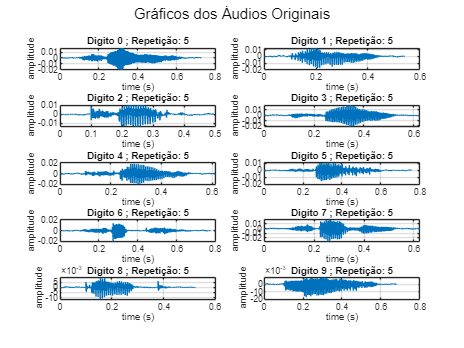

load("dados_audio.mat","dados_audio")
%filtro para escolher só a quinta repetição de cada digito para ser plotada
filter = dados_audio.Repeticao ==5;
reps5 = dados_audio(filter,:); 

nr_linha= 5;
nr_col =2;

figure;
sgtitle("Gráficos dos Áudios Originais"); % Main title for the figure


for i=1:height(reps5)
    filepath=fullfile(reps5.Diretorio{i},reps5.NomeFicheiro{i});
    [y,fs] = audioread(filepath);
    time = (0:length(y)-1)/fs;
    subplot(nr_linha,nr_col,i);
    plot(time,y);
    xlabel("time (s)");
    ylabel("amplitude");
    title(sprintf("Digito %d ; Repetição: 5",reps5.Digito(i)));
    grid on;
end

Escolhemos representar apenas a 5ª repetição de cada digito para agilidade a correr o código.

Analisando os gráficos podemos detetar que: 

- Certos digitos têm picos de altitude menos mais intensos  e outros têm uma distribuição mais uniforme.

- O início do som não é sempre o mesmo: alguns sinais começam mais cedo e outros têm um silêncio inicial mais longo.

- Os sinais têm diferentes padrões de oscilação: Alguns apresentam picos muito definidos e estruturados .Outros têm um padrão mais disperso e irregular. Isso pode indicar diferenças na frequência e articulação dos sons.

- Duração dos sinais varia ligeiramente: A maioria dos sinais está dentro do intervalo de 0.5 a 0.7 segundos. Esta similaridade fez com que decidicemos usar 0.6 segundos como duração para o pre-processamento destes sinais.

## EX4- Pré-processamento

clc; clear; close all;

% Function for trapezoidal energy estimation
function trapezoid_int = trapezoidal_estimation(f_vals, t_vals)
    f_vals = f_vals(:);
    t_vals = t_vals(:);
    dt = diff(t_vals);
    trapezoid_int = sum(0.5 * (f_vals(1:end-1) + f_vals(2:end)) .* dt);
end

% Load dataset
load("dados_audio.mat", "dados_audio");
duration = 0.6; % Target duration in seconds

% **Ensure columns exist before processing**
if ~ismember('Sinal_Processado', dados_audio.Properties.VariableNames)
    dados_audio.Sinal_Processado = cell(height(dados_audio), 1);
end
if ~ismember('Taxa_Processada', dados_audio.Properties.VariableNames)
    dados_audio.Taxa_Processada = zeros(height(dados_audio), 1);
end

% Process each audio file
for i = 1:height(dados_audio)
    %%filepath = fullfile(dados_audio.Diretorio{i}, dados_audio.NomeFicheiro{i});
    %%[Y, fs] = audioread(filepath)
    Y=dados_audio.Sinal{i};
    fs=dados_audio.Taxa_de_amostragem(i);
    % Normalize amplitude
    Y = Y / max(abs(Y));
    
    % Compute time vector
    time_vector = (0:length(Y)-1) / fs;
    
    % Compute energy using trapezoidal integration
    energy = zeros(size(time_vector));
    for j = 2:length(time_vector)
        energy(j) = trapezoidal_estimation(Y(1:j).^2, time_vector(1:j));
    end
    
    % Define minimo de energia para aceitar indices (1% de max energy)
    min_energy = 0.01 * max(energy);
    
    % eonctra o 1º index em que energia> min_energy
    valid_ind = find(energy > min_energy, 1, 'first');
    
    % Remove sliencio inicial
    y_clean = Y(valid_ind:end);

    % Ajuste da duração
    target_samples = round(duration * fs);%nr de samples
    y_length = length(y_clean);
    %se o sinal é menor que 0.6s adiciona silencio no fim senão recorta o
    %excesso
    if y_length < target_samples
        y_clean = [y_clean; zeros(target_samples - y_length, 1)];
    elseif y_length > target_samples
        y_clean = y_clean(1:target_samples);
    end
    %calculo da nova taxa de amostragem
    t_orig = length(Y)/fs;
    fs_pre = fs *(duration/t_orig);

    % Guardar dados na tabela
    dados_audio.Sinal_Processado{i} = y_clean;  % Store as a cell array{}
    dados_audio.Taxa_Processada(i) = fs_pre; 
end

% Save 
save("dados_audio.mat", "dados_audio");




### Etapas de pre-processamento:

**1.Retirar o silêncio inicial de cada sinal: **

É calculada a energia acumulada do sinal(`trapezoidal_estimation`). Depois descobre-se o primeiro indice a partir do qual a energia é superior a 1% da energia máxima(`valid_ind = find(energy > min_energy, 1, 'first')`), depois cria-se `y_clean` começando nesse idice eliminando assim o silêncio inicial.

**2.Normalizar a amplitude:**

A amplitude do sinal é normalizada para o intervalo [-1,1] através da operação `Y/max(abs(Y))`; . Isto garante que variações no volume de gravação não influenciem a análise.

**3.Ajuste da duração dos sinais para 0.6s:**

Se o sinal for mais curto adiciona um silêncio no fim, adicionando zeros ao sinal `y_clean = [y_clean; zeros(target_samples - y_length, 1)]; `, se for mais longo o escesso é cortado `y_clean = y_clean(1:target_samples)`;. Assim garante-se que a duração dos sinais é 0.6s para todos.

**4.Recalculo da taxa de amostragem Pós-Processamento:**

Os sinais sofreram expansões ou truncamentos então as suas taxas de amostragem devem ser recalculadas. Para isto calculámos a duração original do sinal `t_orig, `depois utilizando a` duration `pretendida calculamos a nova taxa de amostragem, `fs_pre = fs *(duration/t_orig);`

## EX5- Representação dos sinais depois do pré-processamento

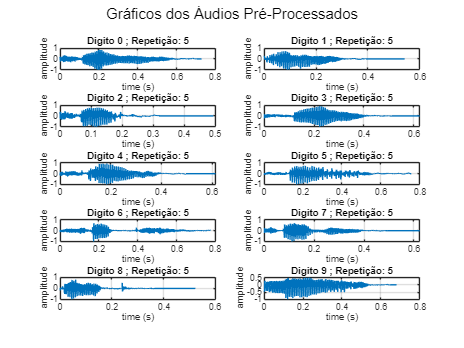


load("dados_audio.mat","dados_audio")
%filtro para escolher só a quinta repetição de cada digito para ser plotada
filter = dados_audio.Repeticao ==5;
reps5 = dados_audio(filter,:); 

nr_linha= 5;
nr_col =2;

figure;
sgtitle("Gráficos dos Áudios Pré-Processados"); % Main title for the figure


for i=1:height(reps5)
    Y=reps5.Sinal_Processado{i};
    fs=reps5.Taxa_Processada(i);
    time = (0:length(Y)-1)/fs;
    subplot(nr_linha,nr_col,i);
    plot(time,Y);
    xlabel("time (s)");
    ylabel("amplitude");
    title(sprintf("Digito %d ; Repetição: 5",reps5.Digito(i)));
    grid on;
end

## EX6- Comparação dos gráficos dos sinais originais e dos gráficos dos sinais pré-processados:

**Remoção de silêncio inicial**

No conjunto de gráficos antes do pré-processamento, alguns sinais começam com um **período de silêncio**. No segundo conjunto, depois do pré-processamento, o início do áudio ocorre mais cedo, sugerindo que o silêncio foi removido.

**Normalização da amplitude**

Antes do pré-processamento, as amplitudes variam muito entre os sinais. Após o pré-processamento, todas as amplitudes foram normalizadas, ficando entre `-1` e `1`.

**Duração uniformizada**

Os sinais originais tinham diferentes durações (`0.6s`, `0.7s`, `0.8s`). Após o pré-processamento, todos os sinais têm exatamente `0.6s`.

Com base na comparação, algumas características que podem ser úteis para diferenciar os dígitos são:

-     Duração do sinal ativo (tempo com energia significativa):Alguns dígitos possuem sinais mais curtos ou longos, mesmo após o pré-processamento.

-     Distribuição da energia ao longo do tempo:Alguns dígitos apresentam picos de energia concentrados no início, enquanto outros têm distribuição mais uniforme.

-     Forma e frequência da oscilação da amplitude:Certos dígitos possuem modulações rápidas, enquanto outros apresentam variações mais suaves na amplitude.

## EX7- Extração da Energia Total, Racio de Energia, Amplitude Max e Min  e  Desvio Padrão da Amplitude

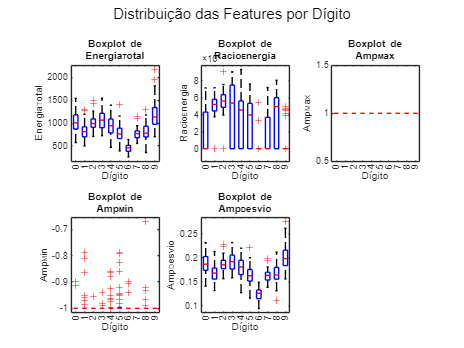

function features = extract_audio_features(y)
   %%num de janelas para análise da energia
    num_intervals = 5;
    interval_length = floor(length(y) / num_intervals);

    %% 1-energia total
    total_energy = sum(y.^2);

   %%2-energia em intervalo
    energy_intervals = zeros(1, num_intervals);
    for i = 1:num_intervals
        idx_start=(i-1)*interval_length + 1;
        idx_end = min(i*interval_length, length(y));
        energy_intervals(i) = sum(y(idx_start:idx_end).^2);
    end

    %%3-razao de intevalo Máxima e Mínima dos Intervalos
    energy_ratio = max(energy_intervals) / max(min(energy_intervals), 1e-6); % Evita divisão por zero

    %%4- amp max e min
    amp_max = max(abs(y));
    amp_min = min(y);

   %%5-desvio 
    amp_std = std(y);

    %%vetor final
    features = [total_energy, energy_ratio, amp_max, amp_min, amp_std];
end

load("dados_audio.mat","dados_audio");
ytest=dados_audio.Sinal_Processado{1};

% **Adicionar colunas para cada feature**
if ~ismember('Energia_Total', dados_audio.Properties.VariableNames)
    dados_audio.Energia_Total = zeros(height(dados_audio), 1);
end
if ~ismember('Racio_Energia', dados_audio.Properties.VariableNames)
    dados_audio.Racio_Energia = zeros(height(dados_audio), 1);
end
if ~ismember('Amp_Max', dados_audio.Properties.VariableNames)
    dados_audio.Amp_Max = zeros(height(dados_audio), 1);
end
if ~ismember('Amp_Min', dados_audio.Properties.VariableNames)
    dados_audio.Amp_Min = zeros(height(dados_audio), 1);
end
if ~ismember('Amp_Desvio', dados_audio.Properties.VariableNames)
    dados_audio.Amp_Desvio = zeros(height(dados_audio), 1);
end

for i=1:height(dados_audio)
    sinal=dados_audio.Sinal_Processado{i};
    features = extract_audio_features(sinal);

    dados_audio.Energia_Total(i)=features(1);
    dados_audio.Racio_Energia(i)=features(2);
    dados_audio.Amp_Max(i)=features(3);
    dados_audio.Amp_Min(i)=features(4);    
    dados_audio.Amp_Desvio(i)=features(5);

end

save("dados_audio.mat","dados_audio")


Foram criadas colunas na tabela de dados para guardar as features calculadas. Escolhemos calcular a energia total, o rácio de energia, amplitudes máxima e minima e o desvio padrão da amplitude.

## EX8- Escolha das features relevantes para a distinção de dígitos

clc; clear; close all;

% Carregar os dados
load("dados_audio.mat", "dados_audio");

% Definir as features e o dígito alvo
features = dados_audio(:, ["Energia_Total", "Racio_Energia", "Amp_Max", "Amp_Min", "Amp_Desvio"]);
digits = dados_audio.Digito;  % Labels dos dígitos 0-9

% Criar Boxplots para análise da separação e decisão das features a
% utilizar para a discriminação de digitos
figure;

A coluna 'Sinal' já não existe.


feature_names = features.Properties.VariableNames;
for i = 1:length(feature_names)
    subplot(2,3,i);
    boxplot(features{:,i}, digits);
    xlabel("Dígito");

Estrutura atualizada e guardada.


    ylabel(feature_names{i});
    title(["Boxplot de", feature_names{i}]);
end
sgtitle("Distribuição das Features por Dígito");

**Features analisadas:**

- **Energia Total**: Há uma variação significativa entre os dígitos, com alguns apresentando valores de energia mais elevados. A separação entre classes não é perfeita, mas há uma tendência de valores diferentes para certos dígitos.

- **Rácio de Energia**: Existe uma variação considerável entre os diferentes dígitos. Alguns dígitos apresentam valores de rácio de energia bem distintos, o que pode facilitar a discriminação.

- **Amplitude Máxima**: A amplitude máxima parece constante para todos os dígitos (valor fixo em 1). Isso indica que essa feature não é útil para diferenciação.

- **Amplitude Mínima**: Apresenta alguma variação, mas não parece ser tão relevante para discriminação dos dígitos.

- **Desvio Padrão da Amplitude**: Apresenta uma boa separação entre diferentes dígitos, sendo uma feature potencialmente relevante.

**Escolha das Três Melhores Features**

Com base na análise dos boxplots e gráficos de dispersão, as três características que melhor distinguem os dígitos são:

- **Energia Total** - Mostra uma variação significativa entre os dígitos.

- **Rácio de Energia** - Apresenta uma boa separação entre classes.

- **Desvio Padrão da Amplitude** - Possui uma distribuição que permite distinguir os dígitos.

Essas três características podem ser utilizadas como base para um classificador, pois apresentam uma boa separação entre os diferentes dígitos.

## EX9-Remover os Sinais importados da tabela

clc; clear; close all;

% **Carregar os dados**
load("dados_audio.mat", "dados_audio");

% **Remover a coluna "Sinal" da estrutura**
if ismember("Sinal", dados_audio.Properties.VariableNames)
    dados_audio.Sinal = [];  % Remove a coluna de sinais brutos
    disp("Coluna 'Sinal' removida.");
else
    disp("A coluna 'Sinal' já não existe.");
end

% **Guardar os dados atualizados sem os sinais brutos**
save("dados_audio.mat", "dados_audio");

disp("Estrutura atualizada e guardada.");

**META 2 **

%% EX10
clc;clear;close all;
load ("dados_audio.mat", "dados_audio")


EX11- Coeficientes de Fourier

%% EX11 – Calcular FFT de todos os sinais
load("dados_audio.mat", "dados_audio");

% Iniciar coluna para FFT, se necessário
if ~ismember('FFT', dados_audio.Properties.VariableNames)
    dados_audio.FFT = cell(height(dados_audio), 1);% Cria coluna vazia de células
end

% Loop para calcular a FFT de cada sinal processado
for i = 1:height(dados_audio)
    y = dados_audio.Sinal_Processado{i}; % sinal pré-processado
    
    fft_result = fft(y); % Calcula a FFT (Fast Fourier Transform
    dados_audio.FFT{i} = fft_result;% Guarda o vetor de FFT na tabela
end

save("dados_audio.mat", "dados_audio");

Neste exercício foi feita a transformação de cada sinal do domínio do tempo para o domínio da frequência através da FFT, que nos permite analisar o conteúdo espectral de cada dígito (quais frequências estão presentes e com que intensidade).

**EX12- Espetro de aplitude Mediano e quartis**

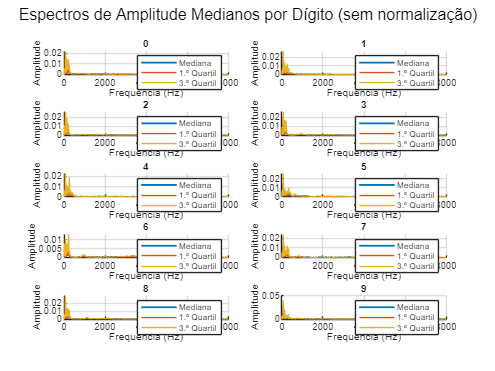

%% EX12 

% Carrega os dados
load('dados_audio.mat');

%  Define os dígitos a analisar e o tamanho da FFT
digitos = 0:9;
Nfft = length(dados_audio.FFT{1});% Tamanho da FFT (assume que todos têm o mesmo)
Fs = dados_audio.Taxa_de_amostragem(1);% Frequência de amostragem (assume igual para todos)

% Inicializar matrizes para guardar estatísticas
mediana_fft = zeros(length(digitos), Nfft);% Mediana do espetro por dígito
q1_fft = zeros(length(digitos), Nfft);% 1.º quartil (25%)
q3_fft = zeros(length(digitos), Nfft); % 3.º quartil (75%)

% Loop por cada dígito
for d = digitos
    idx = find(dados_audio.Digito == d);% Índices de sinais com esse dígito
    fft_stack = zeros(length(idx), Nfft); % Matriz para empilhar os espectros
    
    % Empilha os espectros (amplitude) de cada sinal desse dígito
    for k = 1:length(idx)
        N = length(dados_audio.Sinal_Processado{idx(k)});% Comprimento do sinal

        fft_stack(k, :) = abs(dados_audio.FFT{idx(k)}) / N;% Normaliza e guarda magnitude
    end

    % % Calcula as estatísticas por frequência (coluna a coluna)
    mediana_fft(d+1, :) = median(fft_stack, 1); % Mediana por frequência
    q1_fft(d+1, :) = quantile(fft_stack, 0.25, 1); % 1.º quartil
    q3_fft(d+1, :) = quantile(fft_stack, 0.75, 1); % 3.º quartil
end

% % Frequências associadas ao espetro
f = (0:Nfft-1) * Fs / (2*Nfft);% Calcula vetor de frequências reais até Nyquist

% % Gráfico dos espectros medianos e quartis para cada dígito 5x2
figure;
for d = 0:9
    subplot(5, 2, d+1);
    hold on;
    plot(f, mediana_fft(d+1, :), 'LineWidth', 1.5);
    plot(f, q1_fft(d+1, :) );
    plot(f, q3_fft(d+1, :) );

    title([num2str(d)]);
    xlabel('Frequência (Hz)');
    ylabel('Amplitude');
    xlim([0 8000]);
    legend('Mediana', '1.º Quartil', '3.º Quartil', 'Location', 'northeast');
    grid on;
end

sgtitle('Espectros de Amplitude Medianos por Dígito (sem normalização)');

Através dos gráficos dos espectros de amplitude medianos, conseguimos ver que todos os dígitos concentram a maior parte da energia nas frequências mais baixas, como é habitual na voz humana. No entanto, há diferenças interessantes: por exemplo, os dígitos 6 e 7 destacam-se por terem mais energia em frequências médias, o que os torna diferentes dos restantes. Já dígitos como o 0, 2 e 3 mostram espectros mais "fechados", com a energia mais concentrada no início do gráfico. Também se nota que, dentro de cada dígito, as curvas estão bastante próximas entre si (mediana, 1.º e 3.º quartil), o que indica boa consistência entre amostras. No geral, estes padrões mostram que os espectros de amplitude são úteis para distinguir os diferentes dígitos com base nas suas características em frequência.

**EX 13- Cálculo de Características Espectrais**

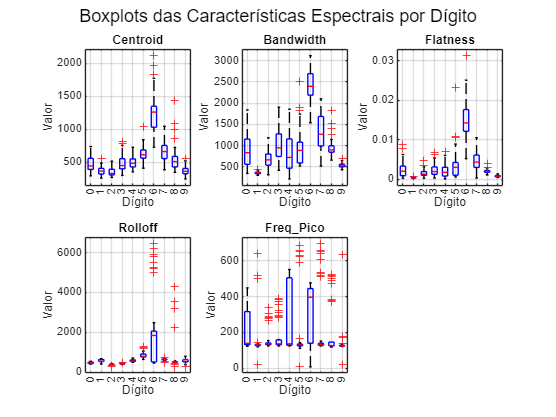

%% EX13 

% inicializa com zeros as colunas novas
dados_audio.Centroid  = zeros(height(dados_audio), 1);
dados_audio.Bandwidth = zeros(height(dados_audio), 1);
dados_audio.Flatness  = zeros(height(dados_audio), 1);
dados_audio.Rolloff   = zeros(height(dados_audio), 1);
dados_audio.Freq_Pico = zeros(height(dados_audio), 1);

% Loop principal para calcular as features espectrais de cada sinal
for i = 1:height(dados_audio)
    % Obter FFT e garantir que é vetor coluna
    X = dados_audio.FFT{i};
    X = X(:);  % garante vetor coluna
    N = length(X);% Número total de pontos da FFT
    
    % Frequências positivas 
    Fs = dados_audio.Taxa_de_amostragem(i);                     % frequência de amostragem do sinal i
    f = (0:floor(N/2))' * (Fs/N);               % vetor de frequências (coluna)
    X_pos = X(1:floor(N/2)+1);                  % FFT parte positiva
    P = abs(X_pos).^2;                          % espectro de potência (magnitude^2)
    
    % 1. Centroide Espectral
    centroid = sum(f .* P) / sum(P);
    dados_audio.Centroid(i) = real(centroid(1));
    
    % 2. Largura de Banda Espectral 
    spread = sqrt(sum(P .* (f - centroid).^2) / sum(P));
    dados_audio.Bandwidth(i) = real(spread(1));

    
    % 3. Flatness Espectral 
    flat_num = exp(mean(log(P + eps)));   % média geométrica (evitando log(0) com eps)
    flat_den = mean(P);                   % média aritmética
    flatness = flat_num / flat_den;
    dados_audio.Flatness(i) = real(flatness(1));
    
    % 4. Spectral Roll-off 
    cumEnergy = cumsum(P);
    threshold = 0.85 * sum(P);
    idx_rolloff = find(cumEnergy >= threshold, 1);
    rolloffFreq = f(idx_rolloff);
    dados_audio.Rolloff(i) = real(rolloffFreq(1));
    
    % 5. Frequência de Pico 
    [~, idx_max] = max(P);
    peakFreq = f(idx_max);
    dados_audio.Freq_Pico(i) = real(peakFreq(1));
end

% Salvar a estrutura de dados atualizada no ficheiro .mat
save('dados_audio.mat', 'dados_audio');



- **Centroide Espectral** – Frequência que representa o centro de gravidade do espectro de magnitude do som�(média ponderada das frequências presentes).

- **Largura de Banda Espectral )** – Desvio padrão das frequências em torno do centroide espectral�, indicando quão espalhado está o espectro em frequência.

- **Flatness Espectral ** – Mede a “planitude” do espectro, dada pela razão entre a média geométrica e a média aritmética do espectro de potência�. Valores altos (~1) indicam espectro plano (sem picos destacados, semelhante a ruído branco), enquanto valores baixos (~0) indicam presença de picos fortes (som tonais).

- **Spectral Roll-off (85%)** – Frequência abaixo da qual se acumula 85% da energia espectral total�. Esta medida dá uma ideia de até onde vai a parte “pesada” do espectro (frequências altas presentes).

- **Frequência de Pico** – A frequência na qual ocorre o pico máximo de amplitude no espectro (ou seja, a componente de frequência dominante no sinal)

Cada uma dessas características espectrais enriquecem a representação dos dígitos, capturando informações sobre distribuição de energia em frequência que podem ajudar a distingui-los. Por exemplo, o centroide e roll-off estão ligados ao conteúdo em altas frequências de cada dígito, enquanto a flatness distingue espectros tonais de espectros ruidosos.


%% EX14 – Boxplots das Características Espectrais por Dígito

% Carregar a estrutura atualizada com as novas features
load('dados_audio.mat', 'dados_audio');

% Lista das características a representar
features = {'Centroid', 'Bandwidth', 'Flatness', 'Rolloff', 'Freq_Pico'};

% Criar figura com subplots
figure;
sgtitle('Boxplots das Características Espectrais por Dígito');

for i = 1:length(features)
    subplot(2, 3, i); % 2 linhas, 3 colunas
    boxplot(dados_audio.(features{i}), dados_audio.Digito);
    title(features{i}, 'Interpreter', 'none');
    xlabel('Dígito');
    ylabel('Valor');
    grid on;
end


Após análise dos boxplots das cinco características espectrais extraídas, concluímos que as três com maior potencial discriminativo entre os dígitos são: Flatness, Rolloff (85%) e Centroid. Estas características mostraram maior separação entre os grupos, menor sobreposição e maior consistência estatística, sendo por isso as mais indicadas para tarefas de reconhecimento automático de dígitos com base nas suas propriedades espectrais. Ainda assim, reconhecemos que a Bandwidth é também uma característica válida, com boa capacidade discriminativa, e poderá ser utilizada como complemento ou substituição em metas futuras.

**META 3:**

**17- Determinação de digitos**

%%

Percentagem de acertos: 42.00% (63/150)


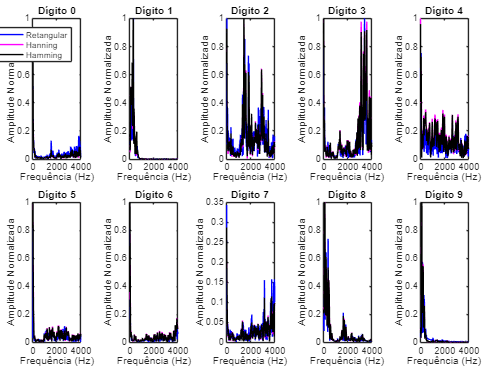

% Carregar dados
load('dados_audio.mat'); % assume que a variável principal se chama "dados_audio"

% Inicializações
digitos = unique(dados_audio.Digito);
num_digitos = numel(digitos);
train_features = [];
train_labels = [];
test_features = [];
test_labels = [];
test_indices = [];  % <- para guardar os índices na tabela original

% Para cada dígito, dividir os dados por repetição (70% treino, 30% teste)
for d = 1:num_digitos
    digito_atual = digitos(d);
    idx = find(dados_audio.Digito == digito_atual);  % guardar como índices
    dados_digito = dados_audio(idx, :);

    % Ordenar por número de repetição
    dados_digito = sortrows(dados_digito, 'Repeticao');
    idx_sorted = idx; % para acompanhar os índices originais
    [~, ordem] = sort(dados_audio.Repeticao(idx));
    idx_sorted = idx(ordem);

    % Dividir 70/30
    total = height(dados_digito);
    num_train = round(0.7 * total);

    dados_train = dados_digito(1:num_train, :);
    dados_test = dados_digito(num_train+1:end, :);
    idx_test = idx_sorted(num_train+1:end); % guardar índices de teste

    % Features
    train_f = [dados_train.Energia_Total, dados_train.Centroid, dados_train.Rolloff];
    test_f = [dados_test.Energia_Total, dados_test.Centroid, dados_test.Rolloff];

    train_features = [train_features; train_f];
    train_labels = [train_labels; repmat(digito_atual, num_train, 1)];

    test_features = [test_features; test_f];
    test_labels = [test_labels; repmat(digito_atual, height(dados_test), 1)];
    test_indices = [test_indices; idx_test]; % guardar os índices reais na tabela
end

% Calcular centroides para cada dígito
centroids = zeros(num_digitos, 3);
for d = 1:num_digitos
    idx = train_labels == digitos(d);
    centroids(d,:) = mean(train_features(idx,:), 1);
end

% Classificar os dados de teste
predicted = zeros(size(test_labels));
for i = 1:size(test_features,1)
    dist = vecnorm(centroids - test_features(i,:), 2, 2);
    [~, min_idx] = min(dist);
    predicted(i) = digitos(min_idx);
end

% Avaliar resultados
acertos = sum(predicted == test_labels);
total_testes = numel(test_labels);
precisao = acertos / total_testes * 100;
fprintf('Percentagem de acertos: %.2f%% (%d/%d)\n', precisao, acertos, total_testes);

% GUARDAR RESULTADO NA TABELA
dados_audio.Digito_Predito = NaN(height(dados_audio), 1);  % inicializar a nova coluna
dados_audio.Digito_Predito(test_indices) = predicted;      % guardar apenas nas amostras testadas

% Atualizar o ficheiro
save('dados_audio.mat', 'dados_audio');

O classificador de distância mínima, utilizando as características *Energia Total*, *Centroid* e *Rolloff*, obteve uma percentagem de acertos de 42%.

Este valor indica que, apesar das características escolhidas permitirem alguma distinção entre os dígitos, o desempenho ainda está aquém do desejável. Algumas possíveis causas incluem:

- Sobreposição nas características entre certos dígitos, especialmente aqueles com forma de onda ou conteúdo espectral semelhantes (ex.: 3 e 5, ou 7 e 9).

- Pouco número de características: foram usadas apenas três, o que pode limitar a capacidade de discriminação do modelo.

- Simplicidade do classificador: o método de distância mínima assume que os dados de cada classe se distribuem em torno de um centro (média), o que pode não ser realista para dados de voz, onde há muita variabilidade.

## 19 - Comparação de janelas: Retangular, Hanning e Hamming

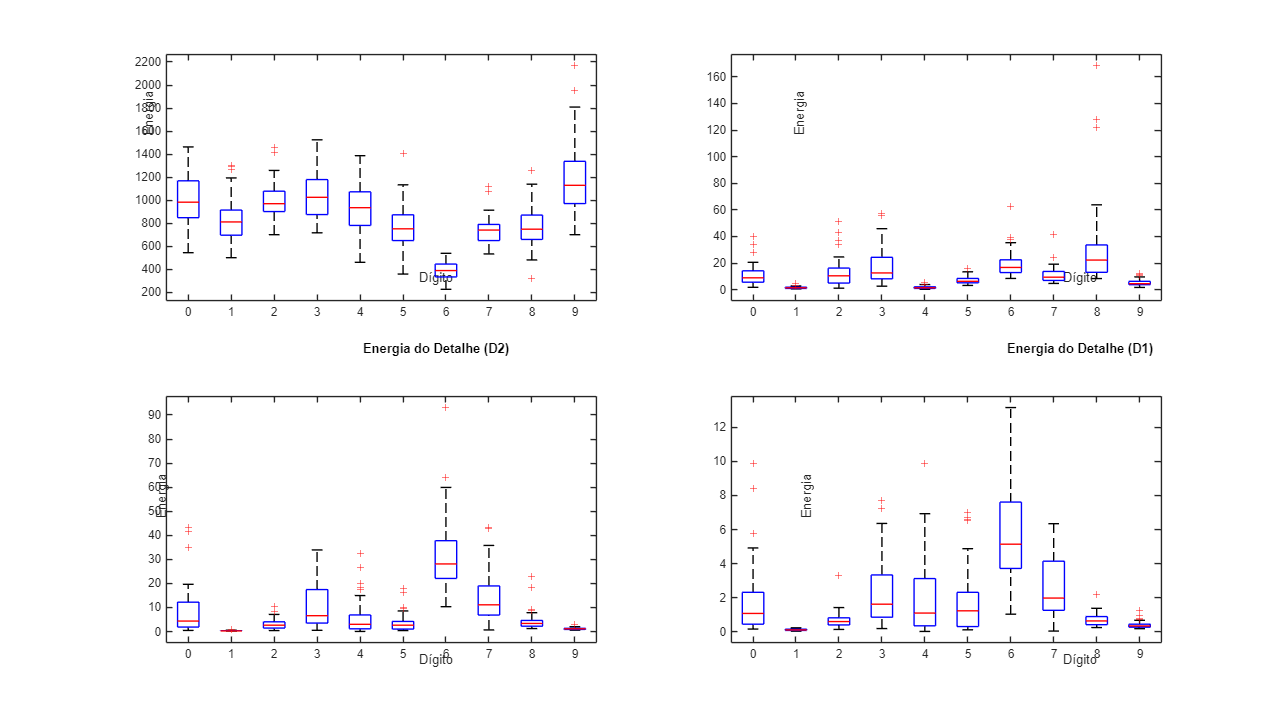

function representar_janelas_fft(dados_audio)
    fs = dados_audio.Taxa_Processada(1); % Corrigido o nome do campo
    janela_len = 2048;               
    janela_ret = rectwin(janela_len);
    janela_han = hann(janela_len);
    janela_ham = hamming(janela_len);

    digitos = 0:9;

    figure('Name', 'Comparação das Janelas - FFT por Dígito');
    tiledlayout(2,5, 'Padding', 'compact', 'TileSpacing', 'compact');

    for d = digitos
        idx = find(dados_audio.Digito == d & dados_audio.Repeticao == 5, 1);
        if isempty(idx), continue; end

        sinal = dados_audio.Sinal_Processado{idx}; % Corrigido o nome do campo
        sinal = sinal(:); % garantir vetor coluna

        % Aplicar janelas e calcular FFT
        [f, mag_ret] = aplicar_janela_fft(sinal, janela_ret, fs);
        [~, mag_han] = aplicar_janela_fft(sinal, janela_han, fs);
        [~, mag_ham] = aplicar_janela_fft(sinal, janela_ham, fs);

        % Gráfico por dígito
        nexttile;
        plot(f, mag_ret, 'b', 'DisplayName', 'Retangular'); hold on;
        plot(f, mag_han, 'm', 'DisplayName', 'Hanning');
        plot(f, mag_ham, 'k', 'DisplayName', 'Hamming');
        title(sprintf('Dígito %d', d));

        xlabel('Frequência (Hz)');
        ylabel('Amplitude Normalizada');
        xlim([0 4000]);

        if d == 0
            legend('show');
        end
    end
end

function [f, mag_norm] = aplicar_janela_fft(sinal, janela, fs)
    % Aplica a janela e calcula FFT normalizada
    N = length(janela);
    if length(sinal) < N
        sinal(N) = 0; % zero padding se necessário
    end
    janela_aplicada = sinal(1:N) .* janela;
    Y = fft(janela_aplicada);
    Y = abs(Y(1:floor(N/2)));
    mag_norm = Y / max(Y); % normalizar
    f = linspace(0, fs/2, length(Y));
end


load('dados_audio.mat'); % Certifique-se que tem os sinais em 'dados_audio'


representar_janelas_fft(dados_audio);


Para analisar o efeito das diferentes janelas (Retangular, Hanning e Hamming), aplicaram-se estas janelas a sinais representativos dos dígitos de 0 a 9 (com repetição 5), e foi realizada a Transformada Rápida de Fourier (FFT) em cada caso. 

Os resultados mostraram diferenças claras no espectro de frequencia resultante: 

-->janela Retangular:apresenta a maior resoluçao de frequencia, com picos espectrais mais definidos, contudo tambem apresenta a maior leakage(vazamento espacial) 

-->janela Hanning: reduz significativamente o leakage, com transiçoes mais suaves.Isto resulta no espectro mais limpo com menor intreferencia entre bandas de frequencia

-->janela Hamming: semelhante à Hanning, mas com ainda melhor supressao do primeiro lóbulo lateral o que ajuda a isular os componentes espectrais, é ideal para distinguir sinais com frequencias proximas

**META 4**


%% Carregar estrutura de dados
clear; clc;
load('dados_audio.mat'); % Certifica-te de que este ficheiro está no diretório

n_amostras = height(dados_audio);


%% Exercício 22 - STFT para cada dígito (repetição 5)
userID = '01';
repeticao = 5; % repeticao escolhida para visualização

janela = hamming(1024);

noverlap = 512;
nfft = 1024;

figure('Units','normalized','Position',[0 0 1 1]);

for digito = 0:9
    idx = find(dados_audio.Digito == digito & dados_audio.Repeticao == repeticao, 1);
    
    if isempty(idx), continue; end

    sinal = dados_audio.Sinal_Processado{idx};
    Fs = dados_audio.Taxa_Processada(idx);


    subplot(5,2,digito+1);
    spectrogram(sinal, janela, noverlap, nfft, Fs, 'yaxis');
    title(sprintf('Dígito %d', digito));
    xlabel('Tempo (s)'); ylabel('Frequência (Hz)');
end

sgtitle('STFT para os Dígitos de 0 a 9 (Repetição 5)');

Neste exercício, foi calculada a **Transformada de Fourier de Curto Prazo (STFT)** para uma amostra representativa de cada dígito (0 a 9), recorrendo à função `spectrogram` do MATLAB.**?**

**Parametrizações utilizadas:**

- **Janela**: `hamming(1024)` – boa definição em frequência com suavização lateral

- **Sobreposição**: `128` amostras – 50% da janela, equilíbrio entre continuidade e independência

- **FFT**: `512` pontos – resolução frequencial adequada para os sinais analisados

Cada espectrograma foi construído a partir de **um mesmo número de repetição (repetição 5)**, permitindo manter a coerência entre os exemplos.

- **Dígitos como “0”, “1” e “2”** apresentam maior concentração de energia nas bandas baixas (até ~1 kHz), com contornos mais suaves.

- **Dígitos como “7”, “8” e “9”** distribuem energia por uma gama de frequências mais ampla, com mais transições e maior densidade espectral.

- **O dígito “9”**, em particular, destaca-se com energia significativa acima dos 2 kHz, o que o torna facilmente identificável visualmente.



%% Exercício 23 - Extrair 5 características tempo-frequência
% Inicializar colunas na estrutura

dados_audio.Energia_STFT = zeros(n_amostras,1);
dados_audio.Num_Picos_STFT = zeros(n_amostras,1);
dados_audio.Freq_Media_STFT = zeros(n_amostras,1);
dados_audio.Desvio_Espectral_STFT = zeros(n_amostras,1);
dados_audio.Freq_Dominante_STFT = zeros(n_amostras,1);

for i = 1:n_amostras
    sinal = dados_audio.Sinal_Processado{i};
    Fs = dados_audio.Taxa_Processada(i);

    [S,F,~] = spectrogram(sinal, janela, noverlap, nfft, Fs);

    S_mag = abs(S);

    dados_audio.Energia_STFT(i) = sum(S_mag(:).^2);
    dados_audio.Num_Picos_STFT(i) = mean(sum(islocalmax(S_mag, 1), 1));
    energia_freq = sum(S_mag, 2);
    dados_audio.Freq_Media_STFT(i) = sum(F .* energia_freq) / sum(energia_freq);
    dados_audio.Desvio_Espectral_STFT(i) = std(S_mag(:));
    [~, idx_max] = max(S_mag, [], 1);
    dados_audio.Freq_Dominante_STFT(i) = mean(F(idx_max));
end

**Características extraídas:**

- **Energia Total da STFT:**Soma dos quadrados dos valores do módulo do espectro. Representa a energia global do sinal no domínio tempo-frequência.

- **Número Médio de Picos Espectrais:**Média do número de picos locais por janela temporal. Indica a complexidade espectral do sinal.

- **Frequência Média Ponderada:**Frequência média calculada com base na distribuição de energia por banda, ponderada pela amplitude espectral.

- **Desvio Espectral:**Desvio padrão das magnitudes espectrais. Mede a dispersão da energia ao longo das frequências.

- **Frequência Dominante Média:**Média das frequências com amplitude máxima em cada janela. Representa a tendência da componente mais forte do sinal.

%% Exercício 24 - Gráficos para análise discriminativa
figure;
gscatter(dados_audio.Freq_Dominante_STFT, dados_audio.Freq_Media_STFT, dados_audio.Digito);
xlabel('Freq. Dominante (Hz)'); ylabel('Freq. Média (Hz)');
title('Discriminação de Dígitos - STFT');

figure;
scatter3(dados_audio.Energia_STFT, dados_audio.Desvio_Espectral_STFT, dados_audio.Num_Picos_STFT, ...
    30, dados_audio.Digito, 'filled');
xlabel('Energia'); ylabel('Desvio'); zlabel('Nº Picos');
title('3D: Características STFT'); colorbar;

Com base nas representações gráficas realizadas (boxplots, gráficos 2D e 3D), as três características extraídas da STFT que apresentaram melhor capacidade de discriminar os dígitos de 0 a 9 foram:**🔹 1. ****Frequência Dominante (Freq_Dominante_STFT)**

No gráfico 2D entre **frequência dominante** e **frequência média**, alguns dígitos, como o “9”, evidenciaram-se claramente com valores muito superiores aos restantes. Esta característica representa a frequência mais energética do sinal ao longo do tempo e revelou-se excelente para separar classes específicas.

**🔹 2. ****Número de Picos Espectrais (Num_Picos_STFT)**

O gráfico 3D mostrou que esta característica contribui para organizar os pontos em regiões distintas. O número de picos dá-nos uma ideia da complexidade espectral do sinal — sinais com mais variações têm mais picos, o que se reflete em diferentes padrões para os dígitos.

**🔹 3. ****Desvio Espectral (Desvio_Espectral_STFT)**

Esta característica mede a dispersão da energia ao longo do espectro. Combinada com o número de picos e a energia, ajudou a formar grupos mais bem definidos no gráfico 3D, distinguindo melhor os sinais mais concentrados dos mais dispersos.

%%25 boxplots DWT por dígito
figure('Name', 'Boxplots das Energias DWT por Dígito', 'Units', 'normalized', 'Position', [0 0 1 1]);

% Aproximação A3
subplot(2,2,1);
boxplot(dados_audio.Energia_Aprox_DWT, dados_audio.Digito);
title('Energia da Aproximação (A3)');
xlabel('Dígito');
ylabel('Energia');

% Detalhe D3
subplot(2,2,2);
boxplot(dados_audio.Energia_Det3_DWT, dados_audio.Digito);
title('Energia do Detalhe (D3)');
xlabel('Dígito');
ylabel('Energia');

% Detalhe D2
subplot(2,2,3);
boxplot(dados_audio.Energia_Det2_DWT, dados_audio.Digito);
title('Energia do Detalhe (D2)');
xlabel('Dígito');
ylabel('Energia');

% Detalhe D1
subplot(2,2,4);
boxplot(dados_audio.Energia_Det1_DWT, dados_audio.Digito);
title('Energia do Detalhe (D1)');
xlabel('Dígito');
ylabel('Energia');

Neste exercício, foi aplicada a **Transformada Wavelet Discreta (DWT)** aos sinais de áudio de cada amostra, utilizando:

- **Wavelet**: Daubechies 4 (`'db4'`)

- **Nível de decomposição**: 3

Foram extraídos os seguintes coeficientes para cada sinal:

- **A3**: aproximação no nível 3

- **D3, D2, D1**: detalhes dos níveis 3, 2 e 1

** Energia da Aproximação (A3)**

- Apresenta maior variação entre os dígitos.

- Os dígitos “6” e “9” distinguem-se claramente com energias médias superiores.

- Excelente para representar o **conteúdo global do sinal**.

**Energia dos Detalhes (D3, D2, D1)**

- As energias dos detalhes são menores em amplitude mas ainda revelam padrões distintos.

- O dígito “6” destaca-se com valores muito mais altos em **D2** e **D1**, indicando transições mais abruptas.

- Os dígitos “0”, “1” e “4” mantêm energia mais baixa e concentrada.

A aplicação da DWT permitiu extrair informações sobre a estrutura do sinal em diferentes resoluções. A energia da aproximação (A3) captou as tendências globais, enquanto as energias dos detalhes (D3, D2, D1) revelaram variações locais e rápidas.

Estas características enriquecem a análise, **complementando a STFT**, e poderão ser integradas no conjunto de atributos para classificação automática de dígitos.

%% Exercício 26 - Guardar a estrutura atualizada
save('dados_audio.mat', 'dados_audio');

